clear; close all;
%% 0. Initialize Parameters
L = 1270; % Length of bridge
n = 1270; % Discretize into 1 mm seg.

x = linspace(0, L, n+1); % x-axis

%% 1. SFD, BMD under train loading
x_train = [52 228 392 568 732 908]; % Train Load Locations
W = 135

W = 135

P_train = [W*1.1/2 W*1.1/2 W/2 W/2 W*1.1*1.35/2 W*1.1*1.35/2];

P = sum(P_train); % Total weight of train [N]

n_train = 856 + L + 1; % num of train locations
SFDi = zeros(n_train, n+1); % 1 SFD for each train loc.
BMDi = zeros(n_train, n+1); % 1 BMD for each train loc.

% Solve for SFD and BMD with the train at different locations
function [A, B] = rxn_forces(Ps, xs, pos, start, stop, length)
    B = dot(Ps(start: stop), xs(start:stop) - 53 + pos - 856 - (length-1200)/2)/1200;
    A = sum(Ps(start:stop)) - B;
end

function weights = w_dist(ws, Ps, xs, pos, start, stop)
    weights = ws;
    for j = start:stop
        weights(xs(j) - 52 + pos - 856) = weights(xs(j) - 52 + pos - 856) - Ps(j);
    end
end
for i = 1:n_train
% start location of train
% sum of moments at A eqn
    F_B = 0;
    F_A = 0;
    if i <= 176
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 6, 6, L);
    elseif i <= 340
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 5, 6, L);
    elseif i <= 516
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 4, 6, L);
    elseif i <= 680
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 3, 6, L);
    elseif i <= 856
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 2, 6, L);
    elseif i > n_train - 176
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 1, 1, L);
    elseif i > n_train - 340
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 1, 2, L);
    elseif i > n_train - 516
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 1, 3, L);
    elseif i > n_train - 680
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 1, 4, L);
    elseif i > n_train - 856
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 1, 5, L);
    else
        [F_A, F_B] = rxn_forces(P_train, x_train, i, 1, 6, L);
    end
% sum of Fy eqn
% construct applied loads
% w(x)
    w = zeros(1, n+1);
    w((L-1200)/2 + 1) = F_A;
    w((L+1200)/2 + 1) = F_B;
    if i <= 176
        w = w_dist(w, P_train, x_train, i, 6, 6);
    elseif i <= 340
        w = w_dist(w, P_train, x_train, i, 5, 6);
    elseif i <= 516
        w = w_dist(w, P_train, x_train, i, 4, 6);
    elseif i <= 680
        w = w_dist(w, P_train, x_train, i, 3, 6);
    elseif i <= 856
        w = w_dist(w, P_train, x_train, i, 2, 6);
    elseif i > n_train - 176
        w = w_dist(w, P_train, x_train, i, 1, 1);
    elseif i > n_train - 340
        w = w_dist(w, P_train, x_train, i, 1, 2);
    elseif i > n_train - 516
        w = w_dist(w, P_train, x_train, i, 1, 3);
    elseif i > n_train - 680
        w = w_dist(w, P_train, x_train, i, 1, 4);
    elseif i > n_train - 856
        w = w_dist(w, P_train, x_train, i, 1, 5);
    else
        w = w_dist(w, P_train, x_train, i, 1, 6);
    end
% SFD = num. integral(w)
    SFDi(i, 1) = w(1);
    for j = 2: n+1
        SFDi(i, j) = SFDi(i, j-1) + w(j);
    end
% BMD = num. integral(SFD)
    BMDi(i, 1) = 0;
    for j = 2: n+1
        BMDi(i, j) = BMDi(i, j-1) + SFDi(i, j-1);
    end
end
SFD = max(abs(SFDi)) %SFD envelope

SFD =   100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  100.2375  296.2277  295.8244  295.4211  295.0177  294.6144  294.2111  293.8078  293.4045  293.0012  292.5979  292.1946  291.7912  291.3879  290.9846  290.5813


BMD = max(abs(BMDi)) %BMD envelope

BMD = 1.0e+04 *

         0    0.0100    0.0200    0.0301    0.0401    0.0501    0.0601    0.0702    0.0802    0.0902    0.1002    0.1103    0.1203    0.1303    0.1403    0.1504    0.1604    0.1704    0.1804    0.1905    0.2005    0.2105    0.2205    0.2305    0.2406    0.2506    0.2606    0.2706    0.2807    0.2907    0.3007    0.3107    0.3208    0.3308    0.3408    0.3508    0.3505    0.3502    0.3500    0.3497    0.3494    0.3491    0.3488    0.3485    0.3482    0.3479    0.3476    0.3501    0.3788    0.4074


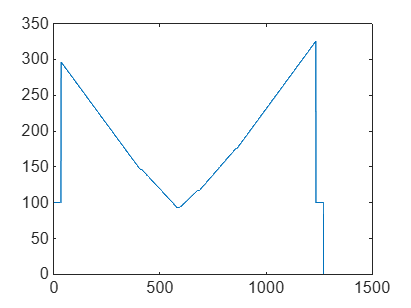

plot(x, SFD)

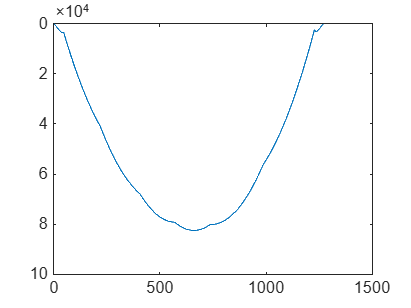

plot(x, BMD)
set(gca, 'YDir','reverse')


%% 2. Define Bridge Parameters 
d = 100     % deck width

d = 100

t = 1.27    % thickness of the board

t = 1.2700

b_h = 120    % total bridge height

b_h = 120

bot = 90    % width of the bottom of the bridge

bot = 90

gt = (bot-2*t)/2      % glue tab width

gt = 43.7300

l = 1       % number of top layers

l = 1

a = 200     % diaphragm spacing

a = 200


%    top            Web 1       Web 2       Glue tab        Glue tab        bottom
b = [d              t           t           gt              gt              bot-2*t]

b =   100.0000    1.2700    1.2700   43.7300   43.7300   87.4600


h = [l*t            b_h-l*t     b_h-l*t     t               t               t]

h =     1.2700  118.7300  118.7300    1.2700    1.2700    1.2700


y = [b_h - l*t/2    (b_h-l*t)/2 (b_h-l*t)/2 b_h-l*t-t/2     b_h-l*t-t/2     t/2]

y =   119.3650   59.3650   59.3650  118.0950  118.0950    0.6350



area_used = L*(d*l + 2*(h(2)+b(4)) + bot) + 6*(100-(l+1)*t)*(bot - 2*t)

area_used = 7.0509e+05

total_area = 813*1016

total_area = 826008


%% 3. Calculate Sectional Properties 

ybar = (sum(b.*h.*y))/(dot(b, h))

ybar = 71.0751

ybot = 0

ybot = 0

ytop = b_h

ytop = 120


I = sum(b.*h.^3/12) + sum(b.*h.*((y - ybar).^2))

I = 1.4885e+06


Qcent = ybar*b(2)*ybar/2 + ybar*b(3)*ybar/2 + h(6)*b(6)*(ybar - y(6))

Qcent = 1.4240e+04


Qglue = b(1)*h(1)*(y(1) - ybar)

Qglue = 6.1328e+03

Q_glue_new = bot*t*(ybar - t/2)

Q_glue_new = 8.0513e+03


%% 4. Calculate Applied Stress 
S_top = BMD(2:n)*(ytop-ybar)/I

S_top =     0.0033    0.0066    0.0099    0.0132    0.0165    0.0198    0.0231    0.0264    0.0297    0.0329    0.0362    0.0395    0.0428    0.0461    0.0494    0.0527    0.0560    0.0593    0.0626    0.0659    0.0692    0.0725    0.0758    0.0791    0.0824    0.0857    0.0890    0.0922    0.0955    0.0988    0.1021    0.1054    0.1087    0.1120    0.1153    0.1152    0.1151    0.1150    0.1149    0.1148    0.1147    0.1146    0.1145    0.1144    0.1144    0.1143    0.1151    0.1245    0.1339    0.1433


S_bot = BMD(2:n)*(ybar-ybot)/I

S_bot =     0.0048    0.0096    0.0144    0.0191    0.0239    0.0287    0.0335    0.0383    0.0431    0.0479    0.0526    0.0574    0.0622    0.0670    0.0718    0.0766    0.0814    0.0862    0.0909    0.0957    0.1005    0.1053    0.1101    0.1149    0.1197    0.1244    0.1292    0.1340    0.1388    0.1436    0.1484    0.1532    0.1579    0.1627    0.1675    0.1674    0.1672    0.1671    0.1670    0.1668    0.1667    0.1665    0.1664    0.1663    0.1661    0.1660    0.1672    0.1809    0.1945    0.2081


T_cent = SFD(1:n)*Qcent/(I*(b(2)+b(3)))

T_cent =     0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    0.3775    1.1157    1.1142    1.1126    1.1111    1.1096    1.1081    1.1066    1.1050    1.1035    1.1020    1.1005    1.0990    1.0974    1.0959    1.0944


T_glue = SFD(1:n)*Qglue/(I*(b(2)+b(3)+b(4)+b(5)))

T_glue =     0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0046    0.0136    0.0135    0.0135    0.0135    0.0135    0.0135    0.0135    0.0134    0.0134    0.0134    0.0134    0.0134    0.0133    0.0133    0.0133


T_glue_new = SFD(1:n)*Q_glue_new/(I*(b(2)+b(3)))

T_glue_new =     0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.2135    0.6308    0.6300    0.6291    0.6282    0.6274    0.6265    0.6257    0.6248    0.6239    0.6231    0.6222    0.6214    0.6205    0.6197    0.6188



%% 5. Material and Thin Plate Buckling Capacities 
E  = 4000; 
mu = 0.2; 
S_tens  =  30*ones(1, n-1)

S_tens =     30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30


S_comp  =  6*ones(1, n-1)

S_comp =      6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6


T_max   =  4*ones(1, n)

T_max =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4


T_gmax  =  2*ones(1, n)

T_gmax =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


S_buck1 =  4*pi^2*E/(12*(1-mu^2))*((h(1)+h(4))/(bot - 2*t))^2*ones(1, n-1)

S_buck1 =    11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615   11.5615


S_buck2 =  0.425*pi^2*E/(12*(1-mu^2))*(2*h(1)/(b(1)-bot))^2*ones(1, n-1)

S_buck2 =    93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645   93.9645


S_buck3 =  6*pi^2*E/(12*(1-mu^2))*(b(2)/(h(2)-ybar))^2*ones(1, n-1)

S_buck3 =    14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033   14.6033


T_buck  =  (5*pi^2*E/(12*(1-mu^2)))*((b(2)/h(2))^2+(b(2)/a)^2)*ones(1, n)

T_buck =     2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514    2.6514



%% 6. FOS 
FOS_tens    =  S_tens./S_bot

FOS_tens = 1.0e+03 *

    6.2680    3.1340    2.0893    1.5670    1.2536    1.0447    0.8954    0.7835    0.6964    0.6268    0.5698    0.5223    0.4822    0.4477    0.4179    0.3918    0.3687    0.3482    0.3299    0.3134    0.2985    0.2849    0.2725    0.2612    0.2507    0.2411    0.2321    0.2239    0.2161    0.2089    0.2022    0.1959    0.1899    0.1844    0.1791    0.1792    0.1794    0.1795    0.1797    0.1798    0.1800    0.1801    0.1803    0.1804    0.1806    0.1807    0.1794    0.1659    0.1542    0.1441


FOS_comp    =  S_comp./S_top

FOS_comp = 1.0e+03 *

    1.8212    0.9106    0.6071    0.4553    0.3642    0.3035    0.2602    0.2276    0.2024    0.1821    0.1656    0.1518    0.1401    0.1301    0.1214    0.1138    0.1071    0.1012    0.0959    0.0911    0.0867    0.0828    0.0792    0.0759    0.0728    0.0700    0.0675    0.0650    0.0628    0.0607    0.0587    0.0569    0.0552    0.0536    0.0520    0.0521    0.0521    0.0522    0.0522    0.0523    0.0523    0.0523    0.0524    0.0524    0.0525    0.0525    0.0521    0.0482    0.0448    0.0419


FOS_shear   =  T_max./T_cent

FOS_shear =    10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954   10.5954    3.5853    3.5902    3.5951    3.6000    3.6049    3.6099    3.6148    3.6198    3.6248    3.6298    3.6348    3.6398    3.6448    3.6499    3.6549


FOS_glue    =  T_gmax./T_glue

FOS_glue =   435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  435.8504  147.4830  147.6841  147.8857  148.0879  148.2906  148.4939  148.6977  148.9021  149.1071  149.3126  149.5187  149.7254  149.9326  150.1404  150.3488


FOS_glue_new = T_gmax./T_glue_new

FOS_glue_new =     9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    9.3696    3.1705    3.1748    3.1792    3.1835    3.1879    3.1922    3.1966    3.2010    3.2054    3.2098    3.2143    3.2187    3.2232    3.2276    3.2321


FOS_buck1   =  S_buck1./S_top

FOS_buck1 = 1.0e+03 *

    3.5092    1.7546    1.1697    0.8773    0.7018    0.5849    0.5013    0.4387    0.3899    0.3509    0.3190    0.2924    0.2699    0.2507    0.2339    0.2193    0.2064    0.1950    0.1847    0.1755    0.1671    0.1595    0.1526    0.1462    0.1404    0.1350    0.1300    0.1253    0.1210    0.1170    0.1132    0.1097    0.1063    0.1032    0.1003    0.1003    0.1004    0.1005    0.1006    0.1007    0.1008    0.1009    0.1009    0.1010    0.1011    0.1012    0.1005    0.0929    0.0863    0.0807


FOS_buck2   =  S_buck2./S_top

FOS_buck2 = 1.0e+04 *

    2.8521    1.4260    0.9507    0.7130    0.5704    0.4753    0.4074    0.3565    0.3169    0.2852    0.2593    0.2377    0.2194    0.2037    0.1901    0.1783    0.1678    0.1584    0.1501    0.1426    0.1358    0.1296    0.1240    0.1188    0.1141    0.1097    0.1056    0.1019    0.0983    0.0951    0.0920    0.0891    0.0864    0.0839    0.0815    0.0816    0.0816    0.0817    0.0818    0.0818    0.0819    0.0820    0.0820    0.0821    0.0822    0.0822    0.0816    0.0755    0.0702    0.0656


FOS_buck3   =  S_buck3./S_top

FOS_buck3 = 1.0e+03 *

    4.4325    2.2162    1.4775    1.1081    0.8865    0.7387    0.6332    0.5541    0.4925    0.4432    0.4030    0.3694    0.3410    0.3166    0.2955    0.2770    0.2607    0.2462    0.2333    0.2216    0.2111    0.2015    0.1927    0.1847    0.1773    0.1705    0.1642    0.1583    0.1528    0.1477    0.1430    0.1385    0.1343    0.1304    0.1266    0.1267    0.1269    0.1270    0.1271    0.1272    0.1273    0.1274    0.1275    0.1276    0.1277    0.1278    0.1269    0.1173    0.1091    0.1019


FOS_buckV   =  T_buck./T_cent

FOS_buckV =     7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    7.0232    2.3765    2.3797    2.3830    2.3863    2.3895    2.3928    2.3961    2.3994    2.4027    2.4060    2.4093    2.4126    2.4160    2.4193    2.4227



%% 7. Min FOS and the failure load Pfail 
minFOS =  min([FOS_tens FOS_comp FOS_shear FOS_glue FOS_buck1 FOS_buck2 FOS_buck3 FOS_buckV])

minFOS = 2.1616

Pf = P*minFOS

Pf = 1.0462e+03


%% 8. Vfail and Mfail
Mf_tens  =  BMD(2:n).*FOS_tens

Mf_tens = 1.0e+05 *

    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829    6.2829


Mf_comp  =  BMD(2:n).*FOS_comp

Mf_comp = 1.0e+05 *

    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255    1.8255


Vf_shear =  SFD(1:n).*FOS_shear

Vf_shear = 1.0e+03 *

    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621    1.0621


Vf_glue  =  min(SFD(1:n).*FOS_glue, SFD(1:n).*FOS_glue_new)

Vf_glue =   939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897  939.1897


Mf_buck1 =  BMD(2:n).*FOS_buck1

Mf_buck1 = 1.0e+05 *

    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176    3.5176


Mf_buck2 =  BMD(2:n).*FOS_buck2

Mf_buck2 = 1.0e+06 *

    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588    2.8588


Mf_buck3 =  BMD(2:n).*FOS_buck3

Mf_buck3 = 1.0e+05 *

    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430    4.4430


Vf_buckV =  SFD(1:n).*FOS_buckV

Vf_buckV =   703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864  703.9864


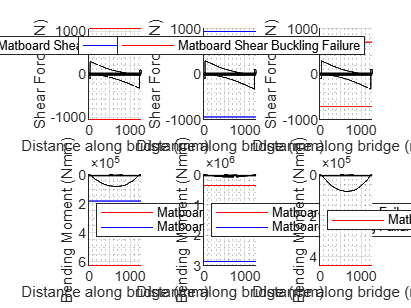


%% 9. Output plots of Vfail and Mfail 
SFDpos = max(SFDi);
SFDneg = min(SFDi);

subplot(2,3,1) 
hold on; grid on; grid minor; 
plot(x(1:n), Vf_shear, 'r') 
plot(x(1:n), -Vf_shear, 'r') 
plot(x, SFDpos, 'k')
plot(x, SFDneg, 'k')
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
legend('Matboard Shear Failure') 
xlabel('Distance along bridge (mm)') 
ylabel('Shear Force (N)') 

subplot(2,3,2) 
hold on; grid on; grid minor; 
plot(x(1:n), Vf_glue, 'b')
plot(x(1:n), -Vf_glue, 'b')
plot(x, SFDpos, 'k')
plot(x, SFDneg, 'k')
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
legend('Glue Shear Failure')
xlabel('Distance along bridge (mm)') 
ylabel('Shear Force (N)') 

subplot(2,3,3) 
hold on; grid on; grid minor; 
plot(x(1:n), Vf_buckV, 'r') 
plot(x(1:n), -Vf_buckV, 'r') 
plot(x, SFDpos, 'k')
plot(x, SFDneg, 'k')
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
legend('Matboard Shear Buckling Failure') 
xlabel('Distance along bridge (mm)') 
ylabel('Shear Force (N)') 

subplot(2,3,4) 
hold on; grid on; grid minor; 
plot(x(2:n), Mf_tens, 'r') 
plot(x(2:n), Mf_comp, 'b') 
plot(x, BMD, 'k')
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
set(gca, 'YDir','reverse')
legend('Matboard Tension Failure', 'Matboard Compression Failure', 'Location', 'west') 
xlabel('Distance along bridge (mm)') 
ylabel('Bending Moment (Nmm)') 

subplot(2,3,5) 
hold on; grid on; grid minor; 
plot(x(2:n), Mf_buck1, 'r') 
plot(x(2:n), Mf_buck2, 'b') 
plot(x, BMD, 'k')
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
set(gca, 'YDir','reverse')
legend('Matboard Buckling Failure, Top Flange - Mid', 'Matboard Buckling Failure, Top Flange - Sides', 'Location', 'west') 
xlabel('Distance along bridge (mm)') 
ylabel('Bending Moment (Nmm)') 

subplot(2,3,6) 
hold on; grid on; grid minor; 
plot(x(2:n), Mf_buck3, 'r') 
plot(x, BMD, 'k')
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
set(gca, 'YDir','reverse')
legend('Matboard Buckling Failure, Webs', 'Location', 'west') 
xlabel('Distance along bridge (mm)') 
ylabel('Bending Moment (Nmm)') 